clear;
load -mat john02_001_000_suite.orisf stat
statc = stat;
load -mat john02_001_001_suite.orisf stat
stati = stat;

contra = 1;
ipsi = 2;
oristim = 0:10:170;
polaredges = -pi/32:pi/16:pi*63/32;



n = size(statc,2);

snr = zeros(n,2);
tmax = zeros(n,2);
sf = zeros(n,2);
ori = zeros(n,2);
cv = zeros(n,2);
f1f0 = zeros(n,2);
kern = cell(n,2);
spks = zeros(n,2);

for i = 1:n
    snr(i,contra) = statc(i).snr;
    snr(i,ipsi) = stati(i).snr;
    tmax(i,contra) = statc(i).tmax;
    tmax(i,ipsi) = stati(i).tmax;
    sf(i,contra) = statc(i).sf_est;
    sf(i,ipsi) = stati(i).sf_est;
    ori(i,contra) = statc(i).ori_est;
    ori(i,ipsi) = stati(i).ori_est;
    oric = statc(i).resp_ori;
    orii = stati(i).resp_ori;
    cv(i,contra) = 1-abs(sum(oric.*exp(1i*2*pi*oristim/180)))/sum(abs(oric));
    cv(i,ipsi) = 1-abs(sum(orii.*exp(1i*2*pi*oristim/180)))/sum(abs(orii));
    f1f0(i,contra) = mean(mean(statc(i).f1f0));
    f1f0(i,ipsi) = mean(mean(stati(i).f1f0));
    kern{i,contra} = statc(i).kern;
    kern{i,ipsi} = stati(i).kern;
    kernc = kern{i,contra};
    kerni = kern{i,ipsi};
    spks(i,contra) = max(kernc(:));
    spks(i,ipsi) = max(kerni(:));
   
end


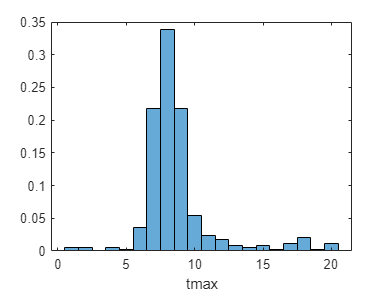

figure,
h = histogram(tmax);
h.Normalization = 'probability';
xlabel('tmax');

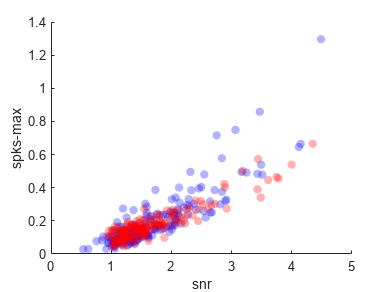


figure
s = scatter(snr(:,1),spks(:,1),40,'blue','filled');   % contra
s.MarkerFaceAlpha = 0.3;
hold on;
s = scatter(snr(:,2),spks(:,2),40,'red','filled');    % ipsi
s.MarkerFaceAlpha = 0.3;
xlabel('snr');
ylabel('spks-max');

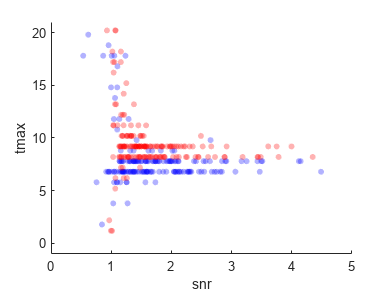


figure,
s = scatter(snr(:,1),tmax(:,1)-0.2,20,'blue','filled');   % contra
s.MarkerFaceAlpha = 0.3;
hold on;
s = scatter(snr(:,2),tmax(:,2)+0.2,20,'red','filled');    % ipsi
s.MarkerFaceAlpha = 0.3;
xlabel('snr');
ylabel('tmax');
ylim([-1 21]);

tmax_all = reshape(tmax,[],1);
snr_all = reshape(snr,[],1);
idx_nr = find(tmax_all<6 | tmax_all>12);
idx_r = find(tmax_all>5&tmax_all<11);
snr_nr = snr_all(idx_nr);
snr_r = snr_all(idx_r);

snr_mean = nanmean(snr_nr);
snr_std = nanstd(snr_nr);
snr_th = snr_mean+3*snr_std

snr_th = 1.5365

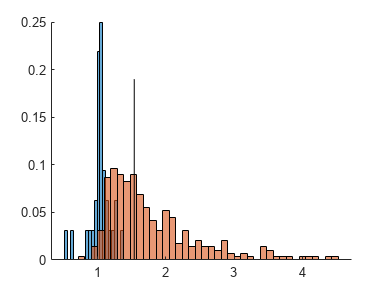

%snr_th = 1.6

figure,
h = histogram(snr_nr,20);
h.Normalization = 'probability';
h.FaceAlpha = 0.6;
hold on;
h = histogram(snr_r,40);
h.Normalization = 'probability';
h.FaceAlpha = 0.6;
line([snr_th snr_th], [0 0.19],'color','k');
box off


cat = zeros(n,1);
for i = 1:n
    if snr(i,contra)<=snr_th & snr(i,ipsi)<=snr_th
        cat(i,1) = 0;
    elseif snr(i,contra)>snr_th & snr(i,ipsi)<=snr_th
        cat(i,1) = 1;
    elseif snr(i,contra)<=snr_th & snr(i,ipsi)>snr_th
        cat(i,1) = 2;
    else
        cat(i,1) = 3;
    end
end

class = accumarray(cat+1,1);
proportion = class/n

proportion =     0.2619
    0.2976
    0.2202
    0.2202


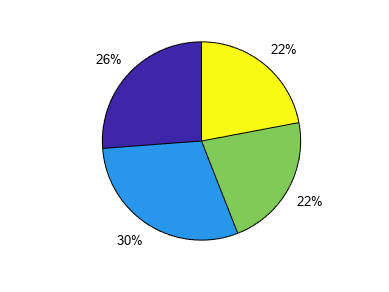


figure,
pie(proportion);

% l = legend('NR','C','I','B');
% l.Box = 'off';
% l.Location = 'best';

idx_c = find(cat==1);
idx_i = find(cat==2);
idx_b = find(cat==3);

ori_mc = ori(idx_c,contra);
sf_mc = sf(idx_c,contra);
cv_mc = cv(idx_c,contra);
f1f0_mc = f1f0(idx_c,contra);
kern_mc = kern(idx_c,contra);


ori_mi = ori(idx_i,ipsi);
sf_mi = sf(idx_i,ipsi);
cv_mi = cv(idx_i,ipsi);
f1f0_mi = f1f0(idx_i,ipsi);
kern_mi = kern(idx_i,ipsi);


ori_bc = ori(idx_b,contra);
sf_bc = sf(idx_b,contra);
cv_bc = cv(idx_b,contra);
f1f0_bc = f1f0(idx_b,contra);
kern_bc = kern(idx_b,contra);


ori_bi = ori(idx_b,ipsi);
sf_bi = sf(idx_b,ipsi);
cv_bi = cv(idx_b,ipsi);
f1f0_bi = f1f0(idx_b,ipsi);
kern_bi = kern(idx_b,ipsi);


nb = class(4);
rf_sim = zeros(nb,1);
for i = 1:nb
    rf_sim(i) = corr2(kern_bc{i},kern_bi{i});
end


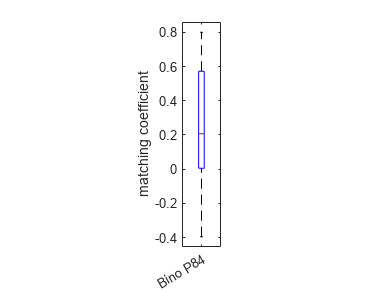

figure,
boxplot(rf_sim,10);
pbaspect([1 6 1]);
xticklabels('Bino P84');
ylabel('matching coefficient');

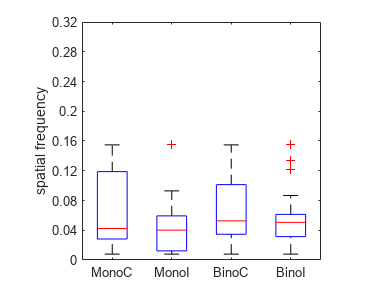

group = [ones(class(2),1);2*ones(class(3),1);3*ones(class(4),1);4*ones(class(4),1)];

figure,
boxplot([sf_mc;sf_mi;sf_bc;sf_bi],group);
pbaspect([1 1 1]);
xticklabels({'MonoC','MonoI','BinoC','BinoI'});
ylabel('spatial frequency');
ylim([0 0.32]);
yticks(0:0.04:0.32);

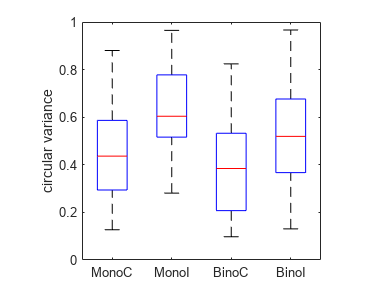


figure,
boxplot([cv_mc;cv_mi;cv_bc;cv_bi],group);
pbaspect([1 1 1]);
xticklabels({'MonoC','MonoI','BinoC','BinoI'});
ylabel('circular variance');
ylim([0 1]);

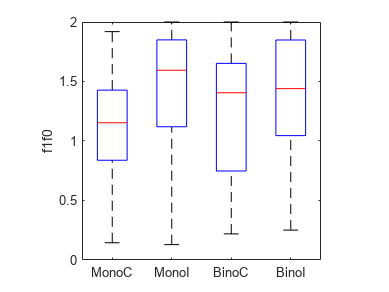


figure,
boxplot([f1f0_mc;f1f0_mi;f1f0_bc;f1f0_bi],group);
pbaspect([1 1 1]);
xticklabels({'MonoC','MonoI','BinoC','BinoI'});
ylabel('f1f0');
ylim([0 2]);

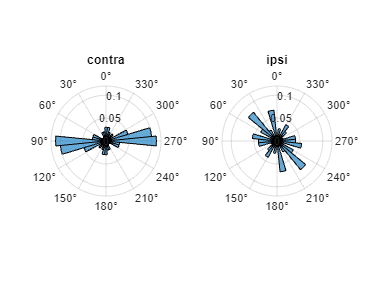




figure,
%sgtitle('Mono');
subplot(1,2,1)
h = polarhistogram([deg2rad(ori_mc);(deg2rad(ori_mc)+pi)],polaredges);
h.Normalization = 'probability';
ax = gca;
ax.ThetaZeroLocation = 'top';
ax.RLim = ([0 0.12]);
title('contra');
subplot(1,2,2),
h = polarhistogram([deg2rad(ori_mi);(deg2rad(ori_mi)+pi)],polaredges);
h.Normalization = 'probability';
ax = gca;
ax.ThetaZeroLocation = 'top';
ax.RLim = ([0 0.12]);
title('ipsi');

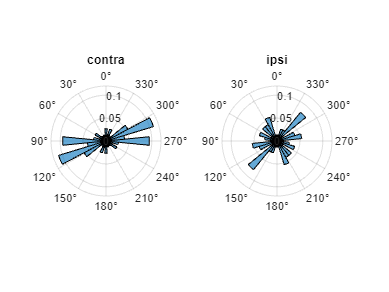



figure,
%sgtitle('Bino');
subplot(1,2,1)
h = polarhistogram([deg2rad(ori_bc);(deg2rad(ori_bc)+pi)],polaredges);
h.Normalization = 'probability';
ax = gca;
ax.ThetaZeroLocation = 'top';
ax.RLim = ([0 0.12]);
title('contra');
subplot(1,2,2),
h = polarhistogram([deg2rad(ori_bi);(deg2rad(ori_bi)+pi)],polaredges);
h.Normalization = 'probability';
ax = gca;
ax.ThetaZeroLocation = 'top';
ax.RLim = ([0 0.12]);
title('ipsi');

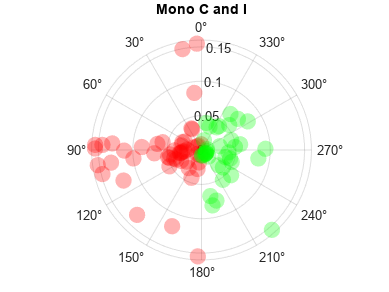

figure,
s = polarscatter(deg2rad(ori_mc),sf_mc,150,'red','filled');
s.MarkerFaceAlpha = 0.3;
hold on;
s = polarscatter(deg2rad(ori_mi)+pi,sf_mi,150,'green','filled');
s.MarkerFaceAlpha = 0.3;
ax = gca;
ax.ThetaZeroLocation = 'top';
ax.RLim = [0 0.16];
title('Mono C and I');

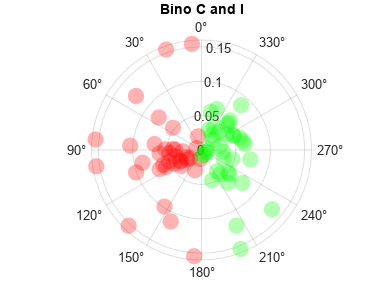


figure,
s = polarscatter(deg2rad(ori_bc),sf_bc,150,'red','filled');
s.MarkerFaceAlpha = 0.3;
hold on;
s = polarscatter(deg2rad(ori_bi)+pi,sf_bi,150,'green','filled');
s.MarkerFaceAlpha = 0.3;
ax = gca;
ax.ThetaZeroLocation = 'top';
ax.RLim = [0 0.16];
title('Bino C and I');

viridis = colormap('viridis');


idxnanmc = find(isnan(f1f0_mc));
f1f0_mc(idxnanmc) = [];
cv_mc(idxnanmc) = [];
sf_mc(idxnanmc) = [];
colormc = zeros(size(cv_mc,1),3);
for i = 1:size(cv_mc,1)
idx = floor(f1f0_mc(i,1)*(255)/2+1);
colormc(i,:) = viridis(idx,:);
end

idxnanmi = find(isnan(f1f0_mi));
f1f0_mi(idxnanmi) = [];
cv_mi(idxnanmi) = [];
sf_mi(idxnanmi) = [];
colormi = zeros(size(cv_mi,1),3);
for i = 1:size(cv_mi,1)
idx = floor(f1f0_mi(i,1)*(255)/2+1);
colormi(i,:) = viridis(idx,:);
end

idxnanbc = find(isnan(f1f0_bc));
f1f0_bc(idxnanbc) = [];
cv_bc(idxnanbc) = [];
sf_bc(idxnanbc) = [];
colorbc = zeros(size(cv_bc,1),3);
for i = 1:size(cv_bc,1)
idx = floor(f1f0_bc(i,1)*(255)/2+1);
colorbc(i,:) = viridis(idx,:);
end

idxnanbi = find(isnan(f1f0_bi));
f1f0_bi(idxnanbi) = [];
cv_bi(idxnanbi) = [];
sf_bi(idxnanbi) = [];
colorbi = zeros(size(cv_bi,1),3);
for i = 1:size(cv_bi,1)
idx = floor(f1f0_bi(i,1)*(255)/2+1);
colorbi(i,:) = viridis(idx,:);
end


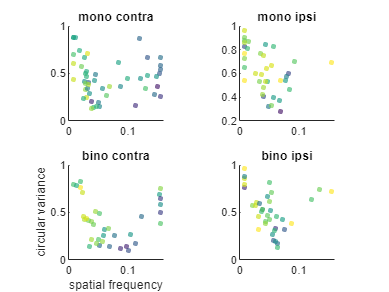

sz = 15;
alpha = 0.65;
figure,
subplot(2,2,1)
s = scatter(sf_mc,cv_mc,sz,colormc,'filled');
s.MarkerFaceAlpha = alpha;
pbaspect([1 1 1]);
title('mono contra');
xlim([0 0.16]);

subplot(2,2,2)
s = scatter(sf_mi,cv_mi,sz,colormi,'filled');
s.MarkerFaceAlpha = alpha;
pbaspect([1 1 1]);
title('mono ipsi');
xlim([0 0.16]);

subplot(2,2,3)
s = scatter(sf_bc,cv_bc,sz,colorbc,'filled');
s.MarkerFaceAlpha = alpha;
pbaspect([1 1 1]);
title('bino contra');
xlabel('spatial frequency');
ylabel('circular variance');
xlim([0 0.16]);

subplot(2,2,4)
s = scatter(sf_bi,cv_bi,sz,colorbi,'filled');
s.MarkerFaceAlpha = alpha;
pbaspect([1 1 1]);
title('bino ipsi');
xlim([0 0.16]);